clear;clc;
load('T.mat');

load('x.mat');
% x=[0.541648131800817
% 0.119561066756382
% 0.00897014122499875
% 0.194327640108857
% -0.0897312131042315
% 0.140651945555938
% 0.382255357942535
% 0.0450393372217192
% 0.470355287538669
% -0.450584252020889
% -0.151500434270185
% -0.280049572248516
% 0.000244847411237942
% -0.457490193964257
% -0.0667355698600076
% -0.461079278667286
% 0.414249779635033
% 0.0215914733244297
% 0.0577379045751080
% -0.343125178736408
% 0.144600581671899
% -0.504396216673201
% -0.0599236173475726
% 0.113084460351966
% 0.00352652475421854
% 0.586862170195492
% 0.0370833237689198
% -0.00450681877757701
% -0.0155556824893279
% -0.0689134582801918
% -0.0857201291911095
% -0.0679452039173198
% -0.274819289417853
% 0.165145062000313
% -0.0648589268726002
% -0.0609827074676872
% 0.0163146200119721
% -0.0914808893307485
% -0.773710669607672
% -0.0973445883407764
% -0.641752454244743
% -0.273373000197032
% -0.244528227246541
% -0.171167376937753
% 0.455660255171590
% 0.0326858046514644
% 0.251504016450947
% -0.0519162460321587
% 0.110820511108205
% -0.0552975043933380
% 0.133099409637985
% -0.291189417164695
% 0.0273756578194732
% 0.0249316240820085
% -0.123298128362014
% -0.0741993185843474
% 0.189485036077966
% 0.185942546759200
% -0.00367771552805284
% 0.00391545077351987
% -0.0311200252761190
% 0.0232031427768059
% -0.0550855685885167
% -0.00840169383421618
% -0.163409656417444
% 0.0136878985187728
% 0.122110056750449
% -0.0711956431405334
% 0.204533352057576
% 0.0989344416175460
% -0.248263252914907
% -0.0176644371105569
% 0.0654194457306887
% -2.65043825484400
% 0.0233939086301247
% 0.446231147250719
% -0.376688483770938];
a = [x(1:7),x(8:14),x(15:21),x(22:28),x(29:35)];  %7 by 5
b = [x(36:42),x(43:49),x(50:56),x(57:63),x(64:70)]; %7 by 5
c = x(71:77); %7 by 1
c(6) = c(6)+0.7;
% x1=[a(1,:)/2,b(1,:)/2,c(1,:)/2;a(2,:)/2,b(2,:)/2,c(2,:)/2;a(3,:)/3,b(3,:)/3,c(3,:)/3;a(4,:)/2,b(4,:)/2,c(4,:)/2;a(5,:)/2,b(5,:)/2,c(5,:)/2;a(6,:),b(6,:),c(6,:)];

% d=zeros(7);
% for o=1:7
%     d(o)=c(o)-sum(b(1,:));
% end
% h = 1/1250;    %采样周期 0.01s
h = 0.001;
T = 10;    %轨迹时间 10s
wf = 2*pi/10; %基频为0.1hz ~ 10s
N=5;          %5次傅里叶叠加
Phi = [];

save_t = [];
save_q = [];
save_q_dot = [];
save_q_ddot = [];

for t = 0:h:T
    q = c;
    q_dot = 0;
    q_ddot = 0;
    for l = 1:N
        q = q+a(:,l)*sin(l*wf*t)/(wf*l) - b(:,l)*cos(l*wf*t)/(wf*l);
        q_dot =  q_dot+a(:,l)*cos(l*wf*t) + b(:,l)*sin(l*wf*t);
        q_ddot = q_ddot-a(:,l)*l*wf*sin(l*wf*t) + b(:,l)*l*wf*cos(l*wf*t);
    end
    save_t = [save_t,t];
    save_q = [save_q,q];
    save_q_dot = [save_q_dot,q_dot];
    save_q_ddot = [save_q_ddot,q_ddot];
    
    %Ys = Y_franka_symoro(q,q_dot,q_ddot);
    %Y = Ys*T_p;
    %Phi = [Phi;Y];
end

Phi_cond = cond(Phi)

Phi_cond = 0

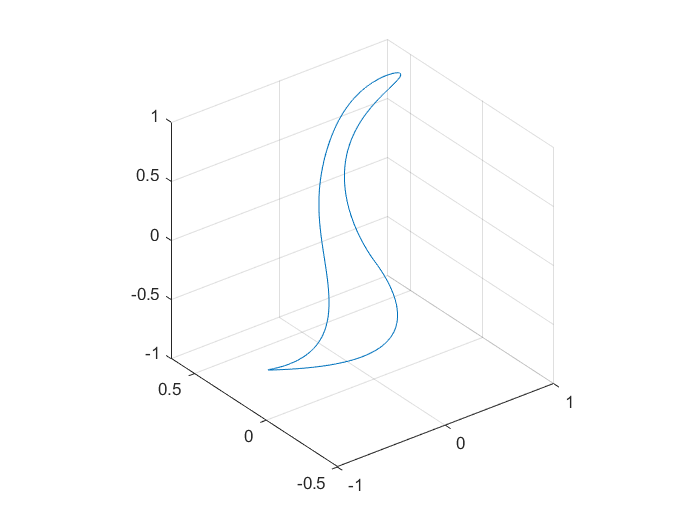


rate = 1.0;
save_q = save_q*rate;
save_q_dot = save_q_dot*rate;
save_q_ddot = save_q_ddot*rate;

period = 3;
save_q = [save_q,save_q,save_q];
save_q_dot = [save_q_dot,save_q_dot,save_q_dot];
save_q_ddot = [save_q_ddot,save_q_ddot,save_q_ddot];
save_t = [save_t,save_t+10,save_t+20];

globalJointCmdPos    = save_q;
globalJointCmdVel    = save_q_dot;
globalJointCmdAcc    = save_q_ddot;
globalEECmdForce     = zeros(size(globalJointCmdPos));
globalJointCmdTorque = zeros(size(globalJointCmdPos));
globalJointActPos    = zeros(size(globalJointCmdPos));
globalJointActVel    = zeros(size(globalJointCmdPos));
globalJointActTorque = zeros(size(globalJointCmdPos));
globalEEActForce     = zeros(size(globalJointCmdPos));
time                 = save_t;

%save_data = [save_t;save_q;save_q_dot;save_q_ddot];
%save_data = [globalJointCmdPos;globalJointCmdVel;globalJointCmdAcc;globalEECmdForce;globalJointCmdTorque;globalJointActPos;globalJointActVel;globalJointActTorque;time];
save_data = [globalJointCmdPos;globalJointCmdVel;globalJointCmdAcc;time];
save('data.mat','save_data');
dlmwrite('franka_data_read_coupled_ident.txt',save_data);

% racer3_data_read.txt
% globalJointCmdPos    6
% globalJointCmdVel    6
% globalJointCmdAcc    6
% time                 1
% TOTAL:6*3+1=19 rows

q_max = max(save_q,[],2);
q_min = min(save_q,[],2);
q_dot_max = max(save_q_dot,[],2);
q_dot_min = min(save_q_dot,[],2);
q_ddot_max = max(save_q_ddot,[],2);
q_ddot_min = min(save_q_ddot,[],2);

% save_q(1,:)=save_q(1,:)/2;
% save_q(2,:)=save_q(2,:)/2;
% save_q(3,:)=save_q(3,:)/3;
% save_q(4,:)=save_q(4,:)/2;
% save_q(5,:)=save_q(5,:)/2;

figure(1)  
for i = 1:7
    subplot(3,3,i)      
    plot(save_t,save_q(i,:))
%     title(['q',num2str(i)])
xlabel('时间/s')
ylabel(['q',num2str(i),'/rad'])

end

% figure(2)
% for i = 1:7
%     subplot(3,3,i)      
%     plot(save_t,save_q_dot(i,:))
%     title(['q_dot',num2str(i)])
% end
% 
% figure(3)
% for i = 1:7
%     subplot(3,3,i)      
%     plot(save_t,save_q_ddot(i,:))
%     title(['q_ddot',num2str(i)])
% end
% 
figure(4)
plot3(save_q(1,:),save_q(2,:),save_q(3,:))
grid on;axis square;